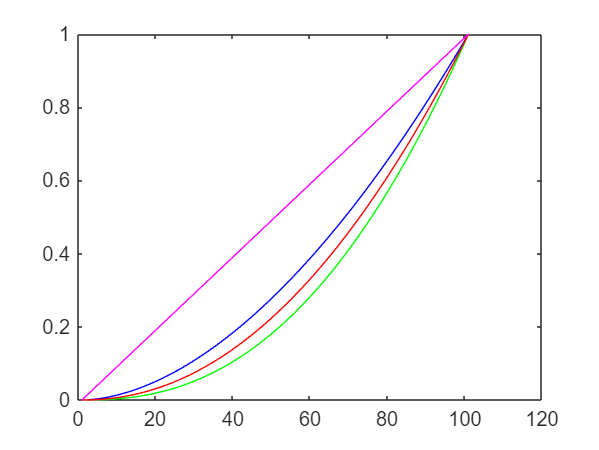

load TRC_display.mat

% upg 1.1
plot(TRCb, 'b')
hold on

plot(TRCg, 'g')
hold on

plot(TRCr, 'r')
hold on

linear = 0:0.01:1;
plot(linear, 'm')


% more blue, less green


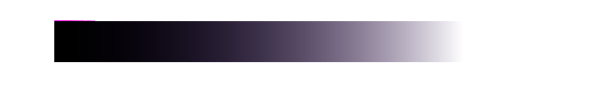

% upg 1.2

load Ramp_display.mat
load Ramp_linear.mat

imshow(Ramp_display)

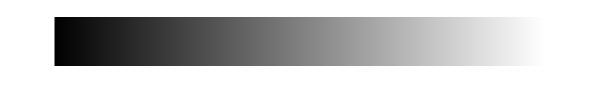


imshow (Ramp_linear)

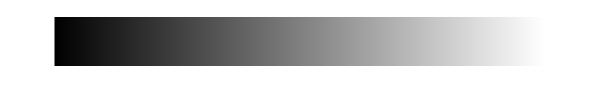


% Calibration

x = 0:0.01:1;

ramp_dispR = interp1(TRCr, x, Ramp_display(:,:,1));
ramp_dispG = interp1(TRCg, x, Ramp_display(:,:,2));
ramp_dispB = interp1(TRCb, x, Ramp_display(:,:,3));


RampDispCorrection = cat(3, ramp_dispR, ramp_dispB, ramp_dispG);
imshow(RampDispCorrection)

% upg 1.3

Yr = 2.1;
Yg = 2.4;
Yb = 1.8;

Dmax = 1;

D_R = Dmax*(Ramp_display(:,:,1)/ Dmax).^(1/Yr);
D_G = Dmax*(Ramp_display(:,:,2)/ Dmax).^(1/Yg);
D_B = Dmax*(Ramp_display(:,:,3)/ Dmax).^(1/Yb);

gammaRampCorrection = cat(3, D_R, D_G, D_B);
imshow(gammaRampCorrection)

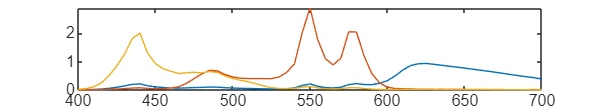

% upg 2.1

load DLP.mat

wavelength = 400:5:700;

plot(wavelength, DLP)


% grön starkast, blå mellan och röd svagast


% upg 2.2

load RGB_raw.mat
load xyz.mat
load illum.mat
load XYZ_ref.mat


k = 100./(CIED65*xyz(:,2));

% convert spectral radiance to XYZ
s_rgb = DLP*RGB_raw;
observer = k * (xyz' * s_rgb);
[L, a, b] = xyz2lab(observer(1,:)', observer(2,:)', observer(3,:)');

REF_Lab = zeros(3,20);
REF_Lab(1,:) = L;
REF_Lab(2,:) = a;
REF_Lab(3,:) = b;


% From xyz to lab
[L, a, b] = xyz2lab(XYZ_ref(1,:)', XYZ_ref(2,:)', XYZ_ref(3,:)');

XYZ_REF_Lab = zeros(3,20);
XYZ_REF_Lab(1,:) = L;
XYZ_REF_Lab(2,:) = a;
XYZ_REF_Lab(3,:) = b;

eucDist = CalcED(XYZ_REF_Lab, REF_Lab)

eucDist =   256.4104  141.8856  123.0972  172.1262  684.5237  162.2777   41.6818  112.7166  126.7453  117.0929   83.3966   79.0519  107.9151  384.3135  112.3753   90.5158  607.3253   68.5412  104.1875  164.3736



maxVal = max(eucDist)

maxVal = 684.5237

meanValn= mean(eucDist)

meanValn = 187.0277